### Задание №4.

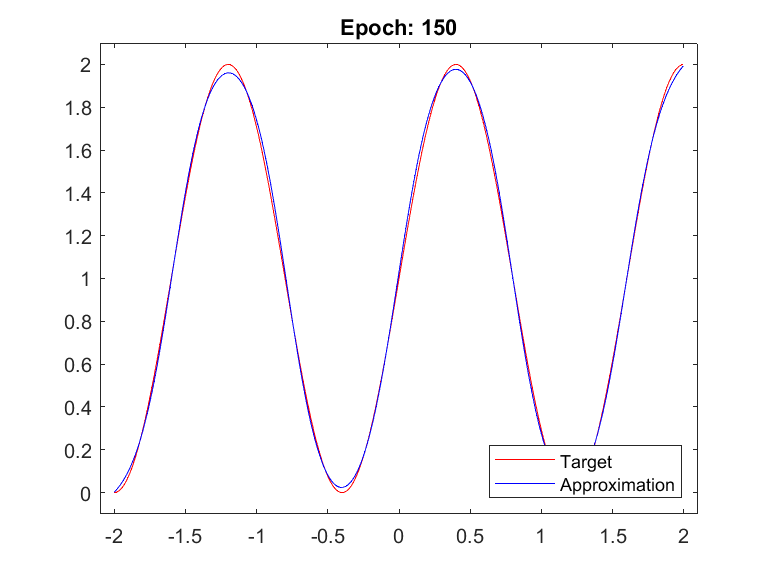

i = 5; 
P = -2:(.4/i):2; 
T = 1 + sin(i*pi*P/4); 
P1 = -2:(.04/i):2; 
T1 = 1 + sin(i*pi*P1/4);

S1 = 5; 
net = fitnet(S1);

net.trainParam.goal = 0.001;
net.trainParam.show = NaN;
net.trainParam.epochs = 1;

[net, tr] = train(net, P, T); 
Y1 = net(P1); 

figure;
epochsNum = 150;
figure;

for i = 1:epochsNum
    [net, tr] = train(net, P, T);
    Y = net(P1);
    
    subplot(1, 1, 1);
    plot(P1, T1, '-r', P1, Y, '-b');
    axis([-2.1, 2.1, -0.1, 2.1]);
    axis manual;
    title(['Epoch: ' num2str(i)]);
    legend({'Target', 'Approximation'}, 'Location', 'southeast');
    
    drawnow;
    
    if strcmp(tr.stop, "Performance goal met.")
        break;
    end
    
    pause(0.1);  
end

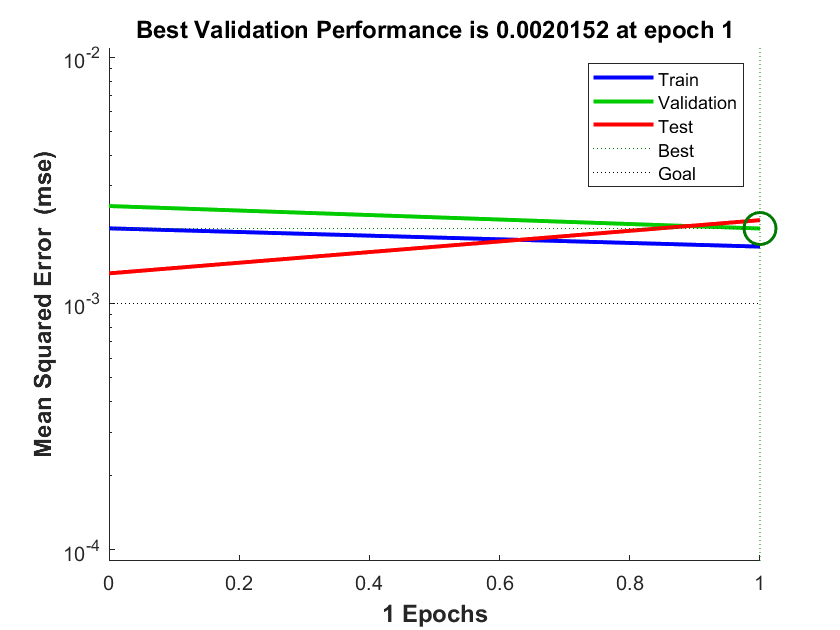

plotperform(tr)
plottrainstate(tr)

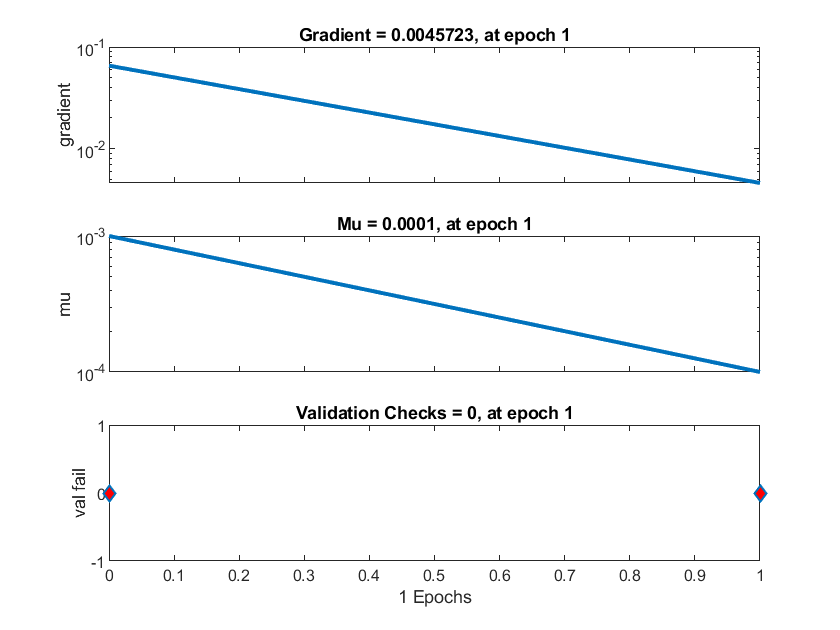

plotfit(net,P1,T1)

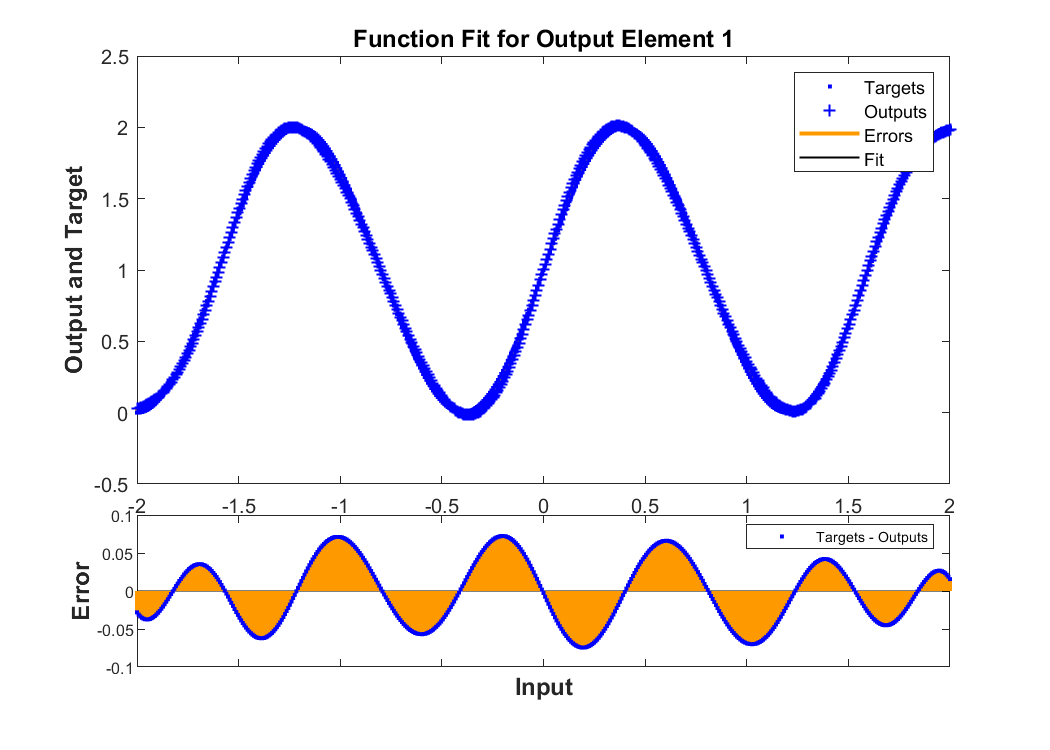

plotregression(T,net(P))

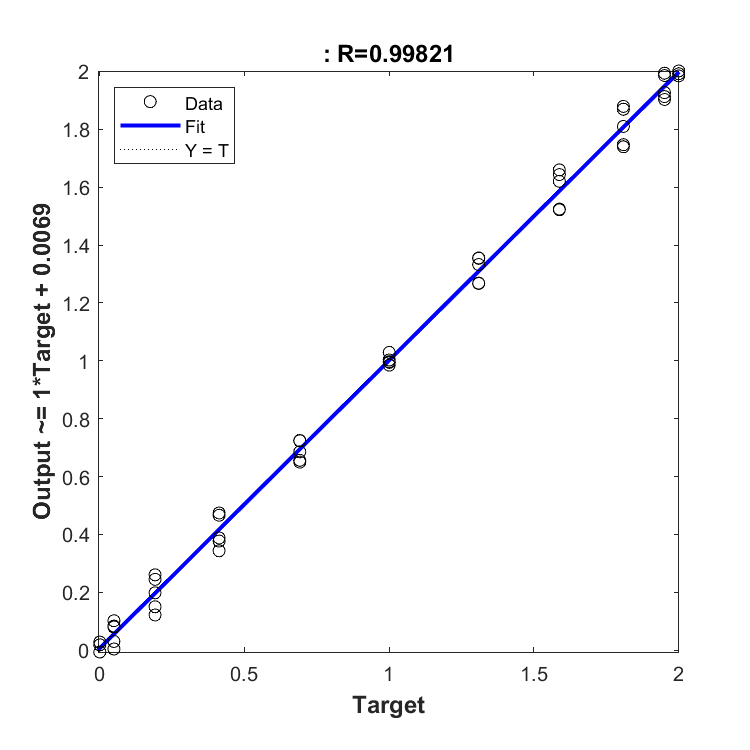

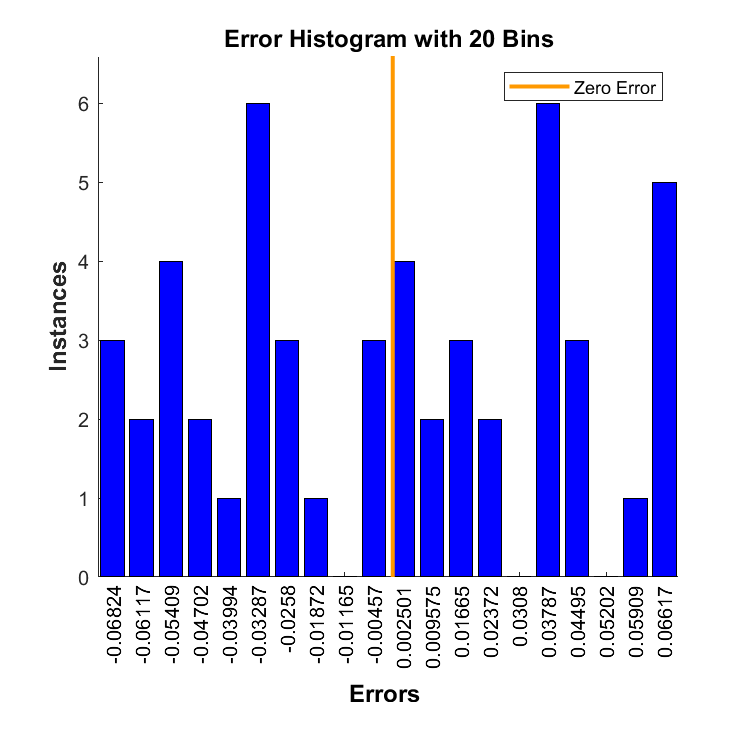

ploterrhist(T-net(P))

### Задание 5. 

Создайте приложение, реализующее Задание 4, с графическим интерфейсом пользователя. 

Значение индекса **i** сложности аппроксимируемой функции и количество нейронов **S1** скрытого слоя должны задаваться при помощи графических компонентов **Slider.**

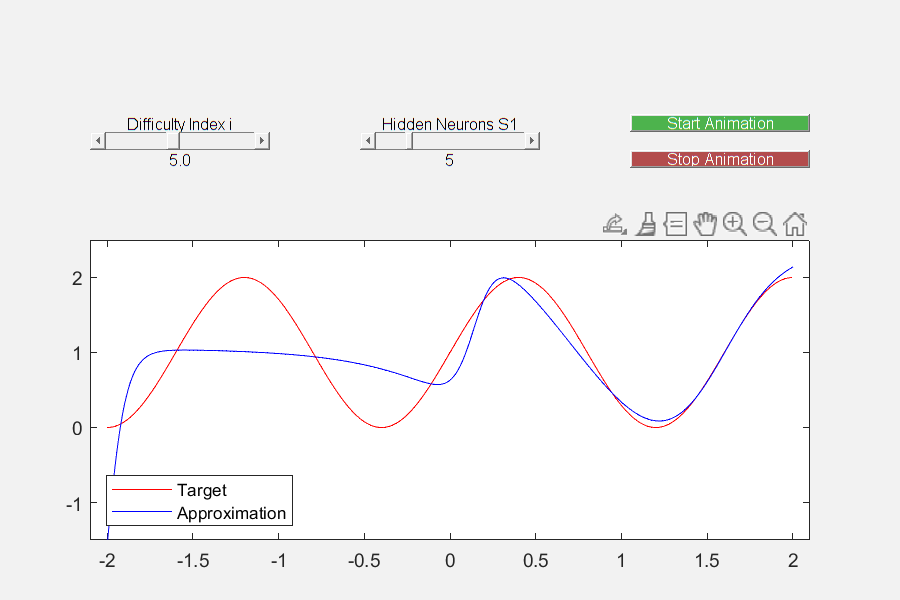

neuralNetworkApp

### Задание 6. 

Аппроксимация функции двух переменных. Самостоятельно сгенерировать и построить 3D-поверхность,  как функцию от двух переменных, сгенерировать обучающее множество точек, принадлежащих данной поверхности (+шум), при помощи сети **fitnet** решить задачу аппроксимации поверхности. Результаты отобразить графически.

rng(1); 
numPoints = 100;
x = rand(numPoints, 1) * 2 - 1; 
y = rand(numPoints, 1) * 2 - 1;
z_true = x.^2 + y.^2; 
noise = 0.1 * randn(size(z_true)); 
z_noisy = z_true + noise; 


net = fitnet(10); % 10 нейронов в скрытом слое
net.trainParam.goal = 0.001;
net.trainParam.epochs = 500;
net = train(net, [x'; y'], z_noisy');


figure;
subplot(1, 2, 1);
scatter3(x, y, z_noisy, 'r.'); % Точки с шумом
title('Noisy Data');

subplot(1, 2, 2);
[x_mesh, y_mesh] = meshgrid(-1:0.1:1, -1:0.1:1);
z_approx = net([x_mesh(:)'; y_mesh(:)']);
z_approx = reshape(z_approx, size(x_mesh));
surf(x_mesh, y_mesh, z_approx, 'FaceAlpha', 0.8);
hold on;
scatter3(x, y, z_noisy, 'r.');
title('Neural Network Approximation');


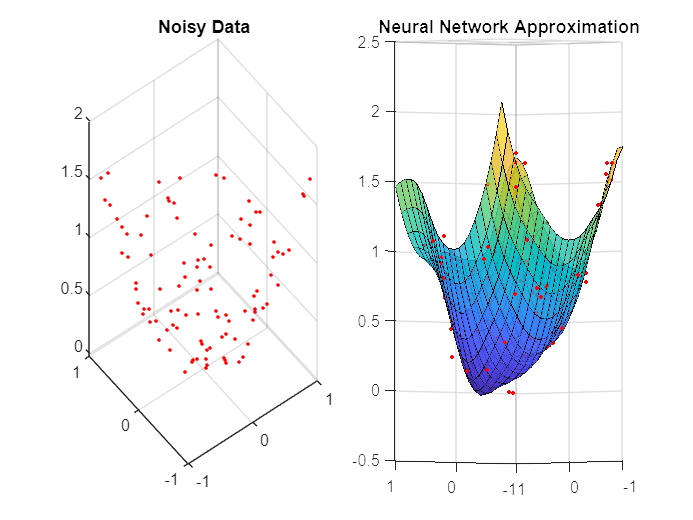

rng(1);
numPoints = 100;

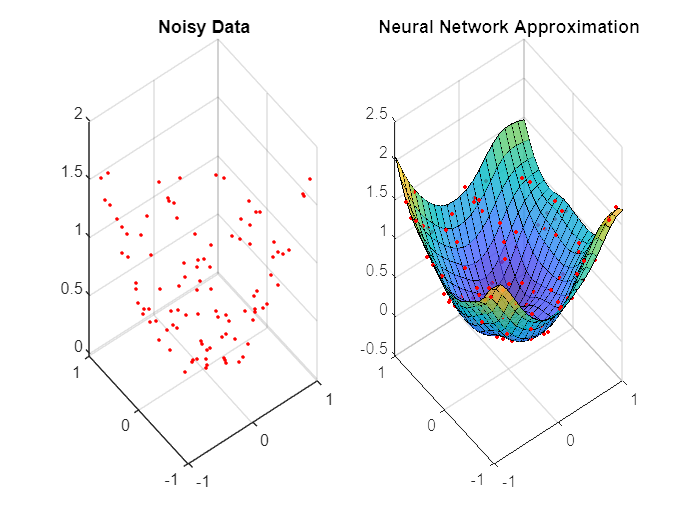

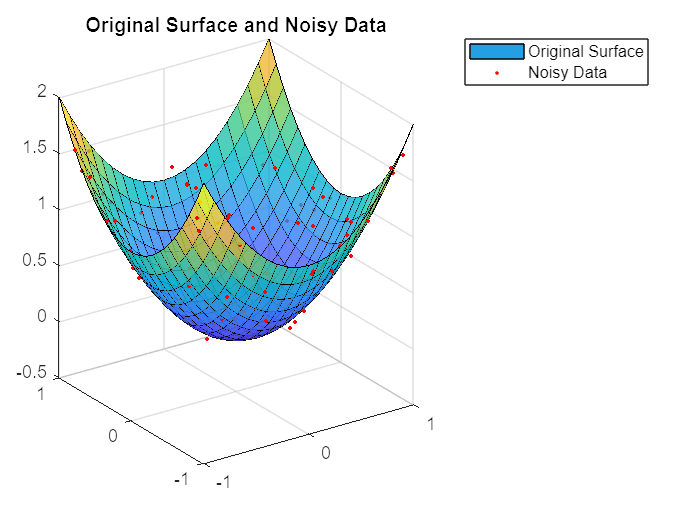

x = rand(numPoints, 1) * 2 - 1;

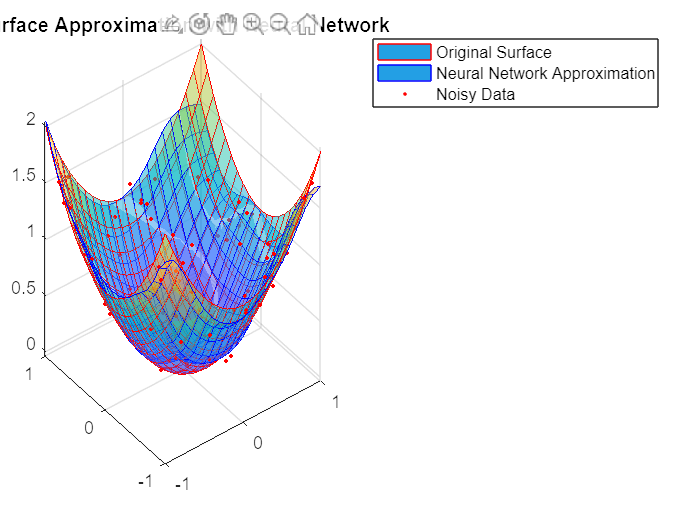

y = rand(numPoints, 1) * 2 - 1;
z_true = x.^2 + y.^2;
noise = 0.1 * randn(size(z_true));
z_noisy = z_true + noise;


net = fitnet(10);
net.trainParam.goal = 0.001;
net.trainParam.epochs = 500;
net = train(net, [x'; y'], z_noisy');


figure;


[x_mesh, y_mesh] = meshgrid(-1:0.1:1, -1:0.1:1);
z_true_mesh = x_mesh.^2 + y_mesh.^2;
z_approx = net([x_mesh(:)'; y_mesh(:)']);
z_approx = reshape(z_approx, size(x_mesh));

surf(x_mesh, y_mesh, z_true_mesh, 'EdgeColor', 'r', 'FaceAlpha', 0.5, 'DisplayName', 'Original Surface');
hold on;
surf(x_mesh, y_mesh, z_approx, 'EdgeColor', 'b', 'FaceAlpha', 0.5, 'DisplayName', 'Neural Network Approximation');
scatter3(x, y, z_noisy, 'r.', 'DisplayName', 'Noisy Data');
title('Surface Approximation with Neural Network');
legend('show');

